# Exercises 5.6

1. For the elements below, determine the nodal forces equivalent to body forces. Consider the element area as A, the thikness as t and the unit weight as γ.

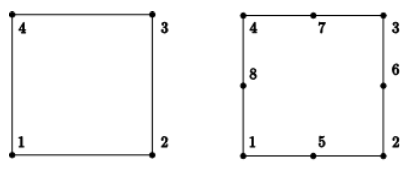

clear all
clc

syms xi eta gamma t A

[dN, N] = quad4_derivs(xi, eta);
int(N,xi,-1,1);
Fe = gamma*t*A/4*int(int(N,xi,-1,1),eta,-1,1)

$$Fe = \left(\begin{array}{c} \frac{A\,\gamma \,t}{4}\\ \frac{A\,\gamma \,t}{4}\\ \frac{A\,\gamma \,t}{4}\\ \frac{A\,\gamma \,t}{4} \end{array}\right)$$

[dN, N] = quad8_derivs(xi, eta);
int(N,xi,-1,1);
Fe = gamma*t*A/4*int(int(N,xi,-1,1),eta,-1,1)

$$Fe = \left(\begin{array}{c} -\frac{A\,\gamma \,t}{12}\\ -\frac{A\,\gamma \,t}{12}\\ -\frac{A\,\gamma \,t}{12}\\ -\frac{A\,\gamma \,t}{12}\\ \frac{A\,\gamma \,t}{3}\\ \frac{A\,\gamma \,t}{3}\\ \frac{A\,\gamma \,t}{3}\\ \frac{A\,\gamma \,t}{3} \end{array}\right)$$